# **Etapa 3 Modelación**

clear; clc;

**Definición de variables**

% Definir m, u, zo, Rring, dt, ds
m = 5000;

zo = 0.5;
R = 1; % Radio ring
dt = 0.01;
ds = 0.01;

E(1) = 0; % FEM inicial
cc = 1;
z(1) = zo;
vz(1) = 0;
g = -9.81;

**Programa**

[Bz(:,:,cc),phi(cc),x,y] = B_due_m(m,z(cc),R,ds);
while z(cc) >= -zo
    pause(0.1);
    %I(1) = E(1) / resistencia; -> parte 3
    % Llamar código step 2, dividir voltaje entre resistencia del anillo,
    % esa corriente la meto
    % [deltaZ * step2(I(cc),R, u, z(c))]; z(c+1) = z(c) + deltaZ;

    z(cc+1) = z(cc) + (vz(cc) * dt) + ((1/2) * g * dt^2);

    [Bz(:,:,cc+1),phi(cc+1),x,y] = B_due_m(m,z(cc+1),R,ds);

    E(cc+1) = (phi(cc+1) - phi(cc)) / dt; % FEM por ley de faraday
    vz(cc+1) = (z(cc+1) - z(cc)) / dt;

    cc = cc + 1;

    if cc > 1
        t = 0:dt:dt*(cc-1);
    end
end

**Graficación**

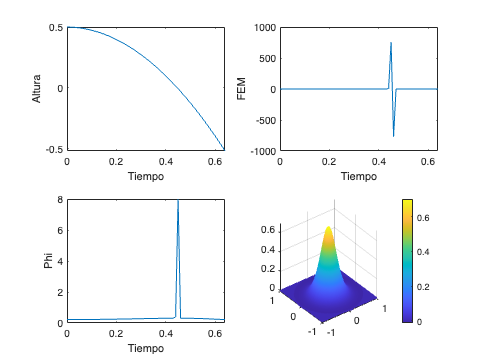

% Crear una figura y establecer la configuración de subplot
figure(1)
subplot(2, 2, 1)
plot(t(1:cc),z(1:cc))
xlabel('Tiempo')
ylabel('Altura')

subplot(2, 2, 2)
plot(t(1:cc),E(1:cc))
xlabel('Tiempo')
ylabel('FEM')

subplot(2, 2, 3)
plot(t(1:cc),phi(1:cc))
xlabel('Tiempo')
ylabel('Phi') % Flujo magnético

% La fuerza electromotriz inducida por el cambio del flujo magnético respecto al tiempo.
% Representación tridimensional del campo magnético en relación con la posición del imán y el anillo.
subplot(2, 2, 4)
mesh(x,y,Bz(:,:,cc))
colorbar

**Definición de la función**

function [Bz, phi, x, y] = B_due_m(m, z, R, ds)
    uo = 4*pi*10e-7;

    x = -R:ds:R;
    y = -R:ds:R;
    Lx = length(x);
    Ly = length(y);
    phi = 0;
    
    % if  (sqrt(x(i)^2 + y(i)^2 + z.^2) <= R)
    for i=1:Lx
        for j=1:Ly
            r = sqrt(x(i)^2 + y(j)^2 + z^2);  % r menor al R
            if sqrt(x(i)^2 + y(j)^2) <= R
                Bz(i,j) = (uo / 4*pi) * (3*(z^2)*m - m*(r^2)) / r^5; % z es rz
                phi = phi + Bz(i,j) * ds^2;
            end
        end
    end
end